# Lab 7: Pulse Oxymetry

**By Ari Porad, April 29th 2021**

**Introduction to Sensors, Instrumentation, and Measurement**

## Abstract

A test subject's heartbeat was measured using a photodiode to measure the optical transparancy of their finger. The output of the photodiode was processed by a high-pass and a low-pass filter, along with two Op-Amp amplifiers, to produce a clean and easily-measurable signal. This method showed great promise as a means of measuring heart rate, although further investigation to evaluate its versatility, accuracy, and equity is required.

## Methodology

We used a photodiode to measure the test subject's pulse by optically measuring the flow of blood in the test subject's finger. The output of the photodiode was processed through an Op-Amp with a 1MΩ resistor and 10nF capacitor for signal amplification and noise reduction. The output of that Op-Amp was fed through a high-pass filter (with a characteristic frequency of 1Hz), another Op-Amp amplifier (with a gain of 11), a low pass filter (with a characteristic frequency of 10Hz), and finally another Op-Amp amplifier (with a gain of 11). This pipeline removes noise from and amplifies the signal so that the pulse can be easily measured without interference. The test subject lightly rested their finger on the photodiode to take the measurement. The characteristic frequencies of the filters were chosen to most easily allow frequencies close to a standard human heart rate (on the order of 1Hz) to pass through, using the formula for the charactaristic frequency of a filter (**Equation 1**).


$$f=\frac{1}{2\pi \mathrm{RC}}$$


**Equation 1.** The formula for the charactaristic frequency of a filter.

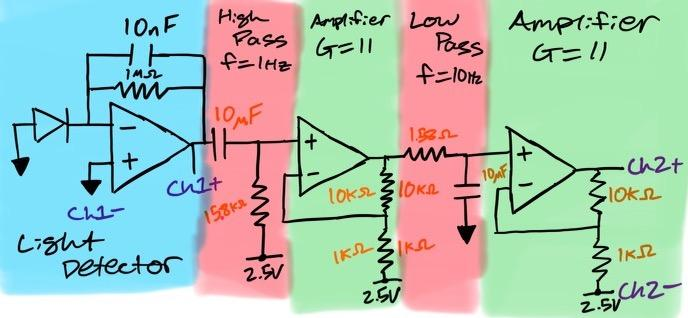

**Figure 1.** A schematic of the circuit we used to measure the test subject's pulse. We used a photodiode, a high-pass filter, a low-pass filter, and an amplifier.

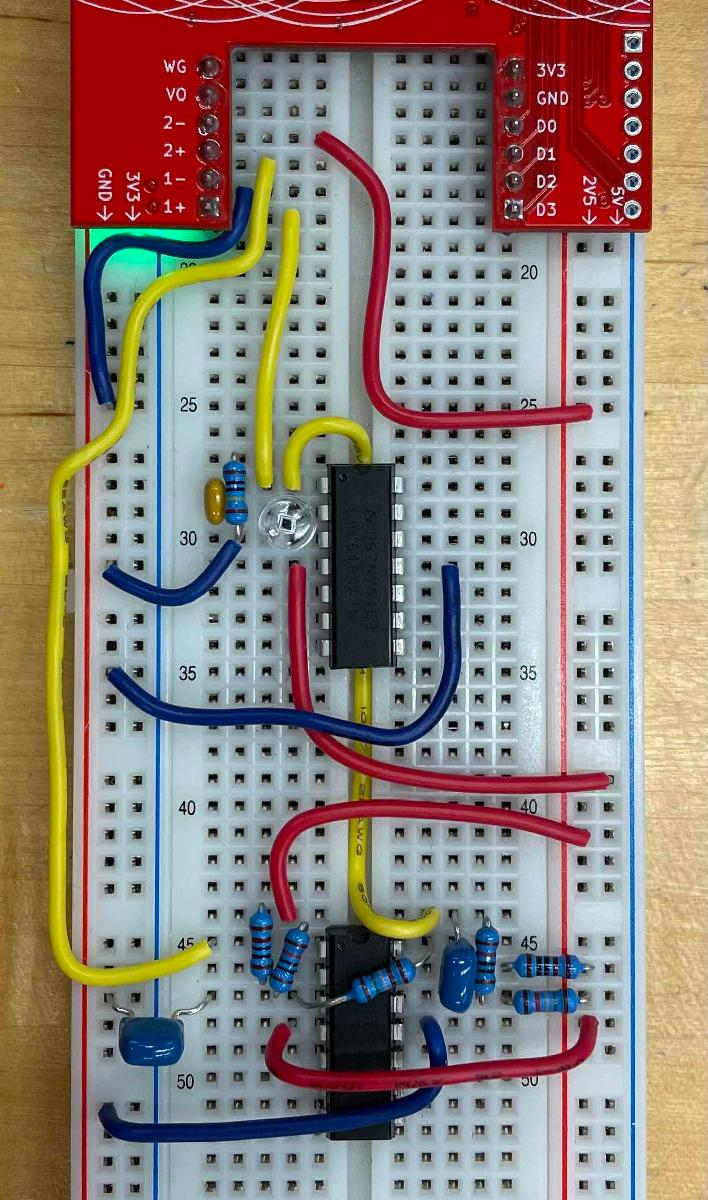

**Figure 2.** The breadboard with our fully-constructed circuit, as described in the above schematic.

## Results

Our system was highly effective at filtering the photoresistor's signal such that the test subject's pulse could be easily read. The photodiode's raw voltage output can be seen below (**Figure 3**), while the processed output with the pulse clearly visible can be seen in **Figure 4**.

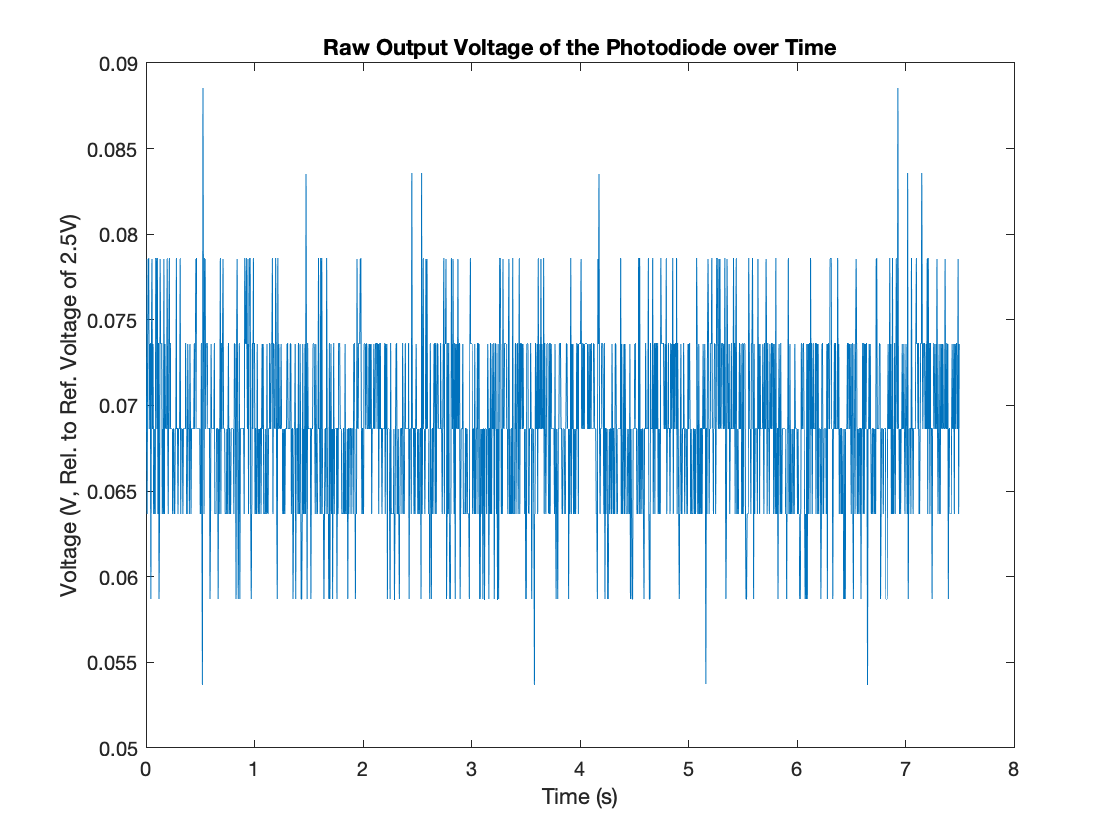

dat = readmatrix("data.csv");
time = dat(:, 1);
time = time - min(time);
raw_voltage = dat(:, 2);
pulse_voltage = dat(:, 4);

figure(3); clf;

plot(time, raw_voltage);
title("Raw Output Voltage of the Photodiode over Time");
ylabel("Voltage (V, Rel. to Ref. Voltage of 2.5V)");
xlabel("Time (s)");

**Figure 3.** Raw output voltage of the photodiode over time. The test subject's pulse cannot be seen.

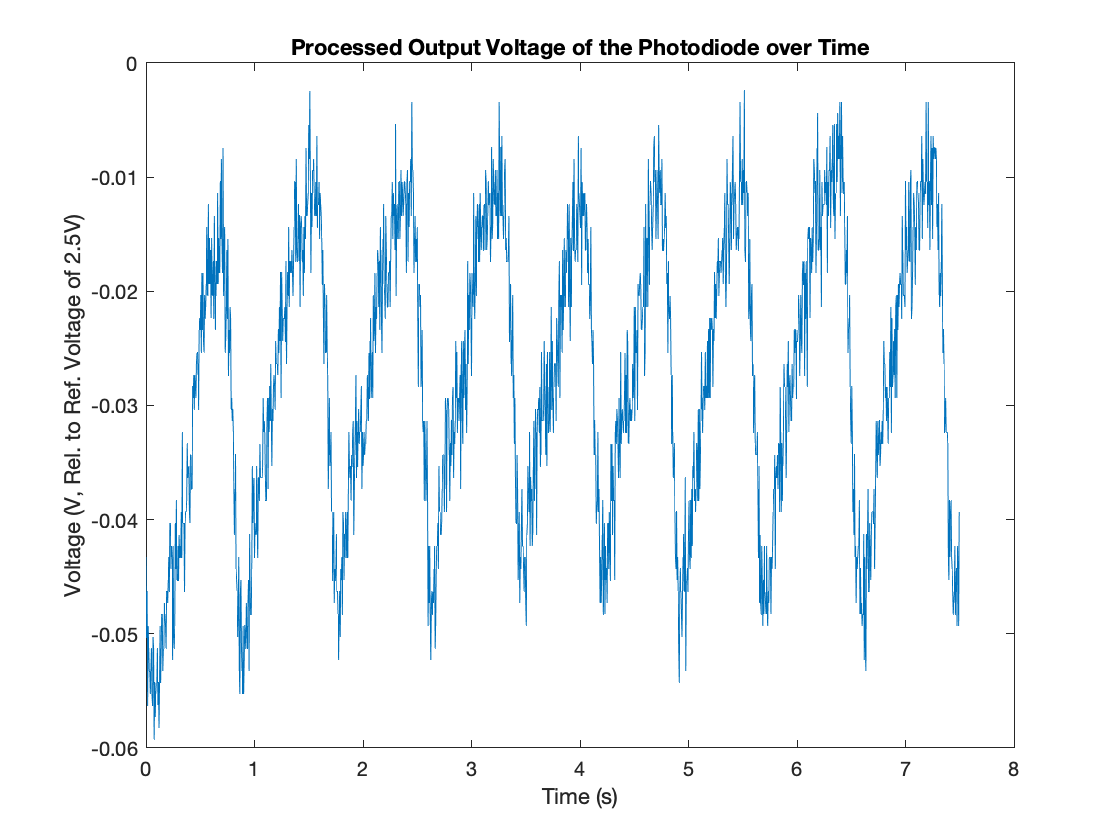

figure(4); clf;

plot(time, pulse_voltage);
title("Processed Output Voltage of the Photodiode over Time");
ylabel("Voltage (V, Rel. to Ref. Voltage of 2.5V)");
xlabel("Time (s)");

**Figure 4.** Processed output voltage over time, with the test subject's pulse clearly visible and other noise filtered out. Each wave represents one heartbeat.

## Finishing Remarks

In this experiment, we demonstrated the viability of using a photodiode to measure a test subject's heartbeat by measuring the circulation through their finger. We also demonstrated the viability of using the above described filtering and amplification techniques to process and clean the photodiode's signal. While that certainly bodes well for the viability of this method, more research is absolutely nessecary to more fully evaluate it in a wider array of circumstances. Further investigation would also be justified into if any other biometrics can me measured through optical means.

Of particular importance for further research would be evaluating the reliability and accuracy of this system in a wider set of test subjects. This experiment only collected data on a healthy 19 year old white male. Given that there's a long history of optical technology (particularly optical technology dependent on shining light through skin) functioning differently for white and nonwhite people, special attention needs to be paid to ensuring this mechanism can function equitably.